ds=imageDatastore("C:\Users\Adarsh Kumar\Desktop\static\srip_prct\srip_colloid","IncludeSubfolders",true,"LabelSource","foldernames")

ds =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Adarsh Kumar\Desktop\static\srip_prct\srip_colloid\00042.tif';
                              'C:\Users\Adarsh Kumar\Desktop\static\srip_prct\srip_colloid\00043.tif';
                              'C:\Users\Adarsh Kumar\Desktop\static\srip_prct\srip_colloid\00044.tif'
                               ... and 2 more
                              }
                     Folders: {
                              'C:\Users\Adarsh Kumar\Desktop\static\srip_prct\srip_colloid'
                              }
                      Labels: [srip_colloid; srip_colloid; srip_colloid ... and 2 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                  

imgc=readimage(ds,2)

imgc = 1944×2592 uint16 matrix
   2110   2057   2036   1852   1832   1714   1708   1507   1418   1342   1272   1147   1082   1008    977    876    874    795    747    709    723    656    618    588    600    580    591    552    551    545    527    545    516    524    568    555    558    514    537    546    568    572    562    561    605    589    573    591    634    638
   2255   2173   2094   2039   1913   1872   1682   1657   1496   1425   1275   1139   1170   1057    983    940    856    822    794    720    688    655    640    600    609    575    568    530    578    519    544    558    556    536    519    523    521    553    571    524    568    608    568    591    625    619    570    622    602    630
   2437   2183   2270   2131   2034   1901   1792   1691   1594   1469   1348   1243   1187   1063   1032    977    914    797    798    711    692    663    657    596    594    538    563    533    525    546    532    536    539    533    536    540    528    523 

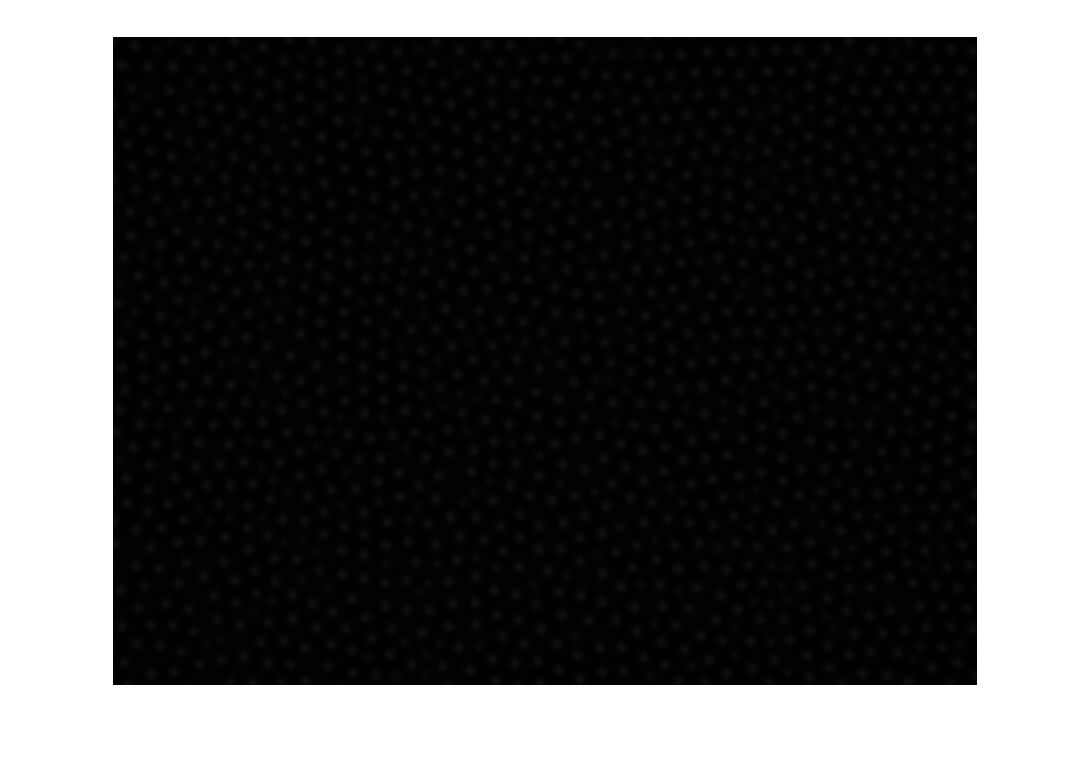

imshow(imgc)

imgcc=imgc>1000

imgcc = 1944×2592 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

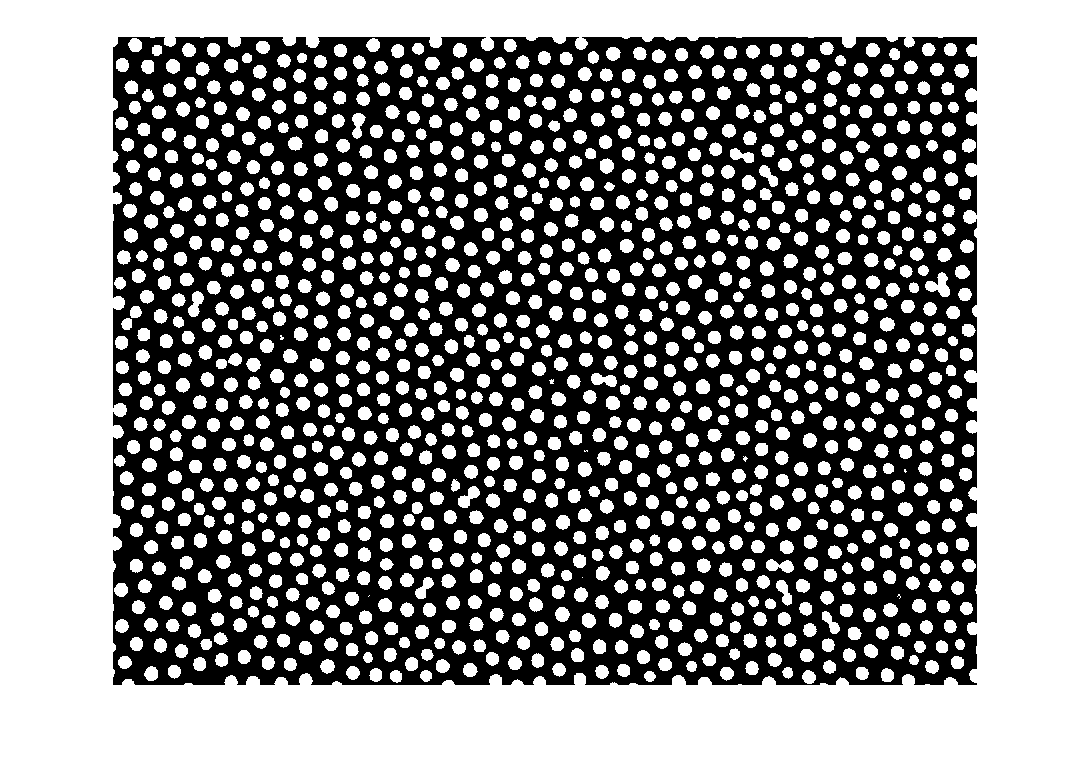

imshow(imgcc)

rs=reshape(img1,[5038848,1])

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.

histogram(rs)            % checking pixel intensity to find threshold for x and y

Unrecognized function or variable 'rs'.

ylabel("Pixel intensity / threshold","Color","g")
xlabel("count","Color","r","FontSize",15)
histogram(rs,10)


circle=regionprops("table",imgcc,"all")

ec=circle.Eccentricity

Unable to resolve the name circle.Eccentricity.

histogram(ec)

Unrecognized function or variable 'ec'.

xlabel("ECENTRICITY    ")
ylabel("particle count","Color","r","FontSize",15)

centre=circle.Centroid

centre = 	1.0e+03 *

    0.0077    0.0141
    0.0010    0.1380
    0.0010    0.1410
    0.0074    0.2024
    0.0010    0.3080
    0.0080    0.3596
    0.0095    0.4258
    0.0130    0.4848
    0.0023    0.5418
    0.0177    0.7985


radius=(circle.MajorAxisLength+circle.MinorAxisLength)/4

radius =    12.2993
    1.1547
    0.5774
   14.1814
    3.4641
   13.8372
   16.2084
   17.0890
    6.6391
   20.3026


imshow(imgcc)
hold on 
viscircles(centre,radius,"color","r","LineWidth",0.7)

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


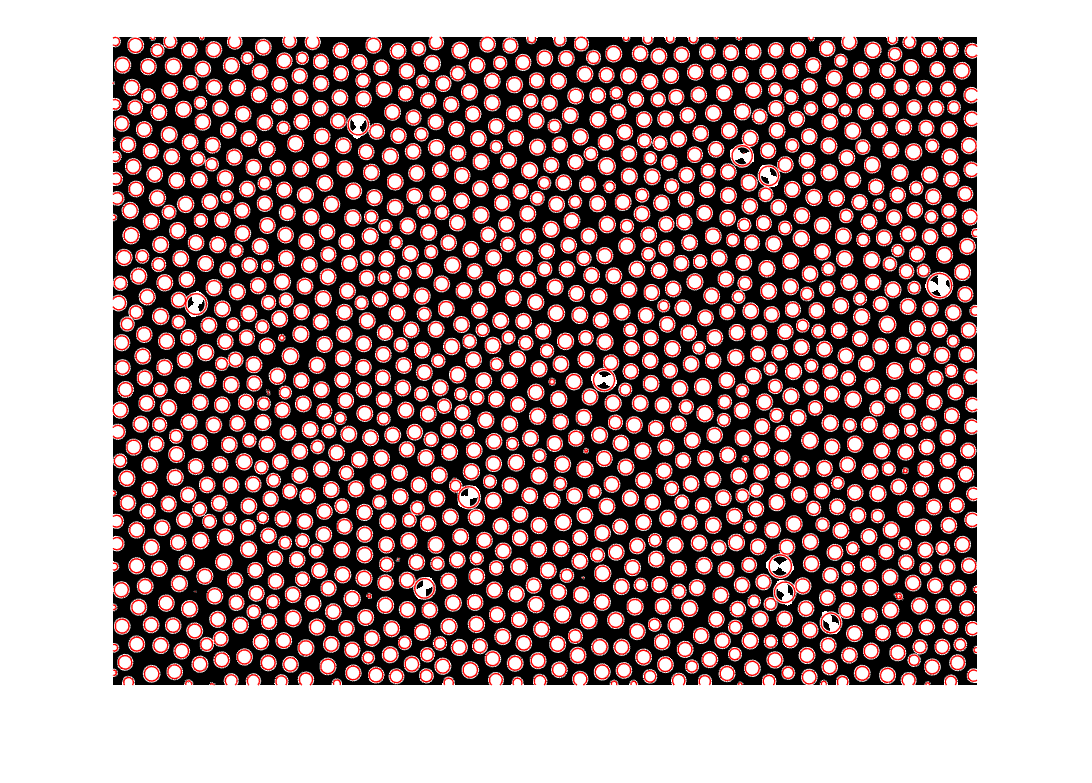

hold off

imshow(imgcc)

circle

circle = 1312×30 table
    Area        Centroid                   BoundingBox                        SubarrayIdx              MajorAxisLength    MinorAxisLength    Eccentricity    Orientation     ConvexHull        ConvexImage      ConvexArea    Circularity         Image           FilledImage      FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent      PixelIdxList         PixelList       Perimeter    PerimeterOld    MaxFeretDiameter    MaxFeretAngle    MaxFeretCoordinates    MinFeretDiameter

r=circle([1:end],["Centroid"])

r = 1312×1 table
        Centroid    
    ________________

    7.6764    14.092
         1       138
         1       141
    7.3785    202.44
         1       308
    8.0216    359.62
    9.4894    425.79
        13    484.83
    2.2817    541.77
    17.738    798.52
    22.066    1119.5
    15.052    1184.9
    1.8627    1369.3
     11.22    1453.1
    12.141    1520.3
    4.1866    1589.4


x=r.Centroid([1:end],[1])

x = 	1.0e+03 *

    0.0077
    0.0010
    0.0010
    0.0074
    0.0010
    0.0080
    0.0095
    0.0130
    0.0023
    0.0177


y=r.Centroid([1:end],[2])

y = 	1.0e+03 *

    0.0141
    0.1380
    0.1410
    0.2024
    0.3080
    0.3596
    0.4258
    0.4848
    0.5418
    0.7985


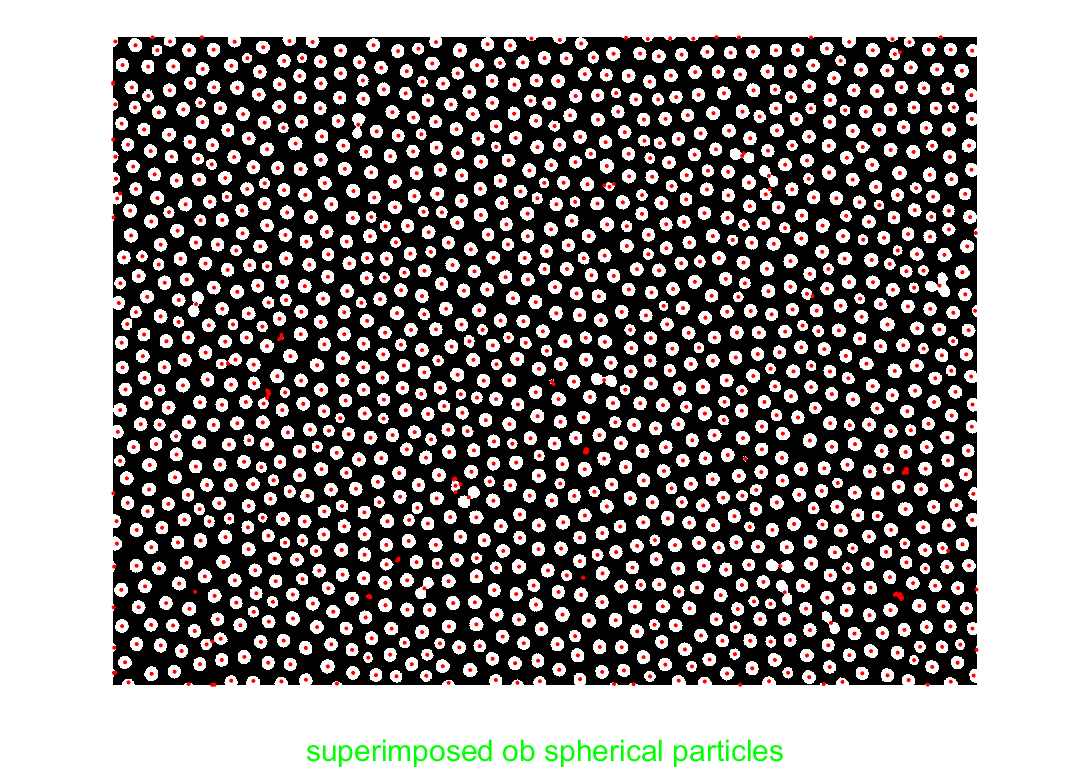

imshow(imgcc)
hold on
plot(x,y,".","Color","r")
xlabel("superimposed ob spherical particles","FontSize",15,"Color","g")
hold off